 clear
 clc

%Set Values
ChordD = struct2array(load('ChordD.mat'));
TwistA = struct2array(load('TwistA.mat'));
 FreeNormVel = 10; % The velocity of wind tunnel (m/s)
 N = 2; % Number Of fans
 row = 1.204;
 kVisc = 1.506e-5;
 Diameter = 0.5;
 slices = 100;
 Mach = 30/343;
 Ncrit = 5;
 aopt = 1/3;
 RootStart = 0.035;
 adashopt = 0.02;
  Constant = (1/2)*row*pi*((Diameter/2)^2)*(10^3)

Constant = 118.2024

 
 ReInit = [57000,57000] %is 59000,57000 idf include sg 6040

ReInit =        57000       57000


 AirfoilChangeR = Diameter/6.5; %Turn into an array if more than one change

 % for i = 1:(length(AirfoilChangeR)+1)
 %      [XFOILA1,DesAlpha(i)] = run_xfoil(SG60(:,((i*2)-1):(i*2)), ReInit(i), Mach, Ncrit, min(alpha_grid), max(alpha_grid)); %Idk why warning it seems to work 
 %  %Calculated from XFOIL data
 %   ForTwstGrphAlpha = DesAlpha;
 %  [~,idx] = min(abs(XFOILA1(:,1)-DesAlpha(i)));
 %  LiftCoef(i) = XFOILA1(idx,2);
 %  end

% ONLY RUN THIS ONCE

 % Sample airfoil coordinates (x, y)
SG60(:,1:2) = table2array(readtable('SG6043cords.csv','PreserveVariableNames',true));
SG60(:,3:4) = table2array(readtable('SG6043cords.csv','PreserveVariableNames',true));

% Example ranges
Re_grid = logspace(4.3, 5.05, 10);        % 10 values 
alpha_grid = linspace(-10, 25, 31);  % -10 to 20 degrees
DesAlpha_table = zeros((length(AirfoilChangeR)+1), length(Re_grid));
for i = 1:(length(AirfoilChangeR)+1)
     [XFOILA1,DesAlpha(i)] = run_xfoil(SG60(:,((i*2)-1):(i*2)), ReInit(i), Mach, Ncrit, min(alpha_grid), max(alpha_grid)); %Idk why warning it seems to work 
 %Calculated from XFOIL data
 ForTwstGrphAlpha = DesAlpha;
 [~,idx] = min(abs(XFOILA1(:,1)-DesAlpha(i)));
 LiftCoef(i) = XFOILA1(idx,2);
    for j = 1:length(Re_grid)
        [XFOIL, ~] = run_xfoil(SG60(:,((i*2)-1):(i*2)), Re_grid(j), Mach, Ncrit, min(alpha_grid), max(alpha_grid));
        % XFOIL(:,1) = alpha, XFOIL(:,2) = CL, XFOIL(:,3) = CD
        CL = XFOIL(:,2);
        CD = XFOIL(:,3);
        CLCD = CL ./ CD;
        [~, idx_max] = max(CLCD);
        DesAlpha_table(i, j) = XFOIL(idx_max, 1); % Store optimum alpha for this Re
        % (Also fill CL_table and CD_table as before)
        for k = 1:length(alpha_grid)
            idx = find(abs(XFOIL(:,1)-alpha_grid(k)) == min(abs(XFOIL(:,1)-alpha_grid(k))), 1);
            CL_table(i,j,k) = XFOIL(idx,2);
            CD_table(i,j,k) = XFOIL(idx,3);
        end
    end
end

 
  XFOIL Version 6.99 
  Copyright (C) 2000   Mark Drela, Harold Youngren 
 
  This software comes with ABSOLUTELY NO WARRANTY, 
    subject to the GNU General Public License. 
 
  Caveat computor 
 
 File  xfoil.def  not found 
 
   QUIT    Exit program 
 
  .OPER    Direct operating point(s) 
  .MDES    Complex mapping design routine 
  .QDES    Surface speed design routine 
  .GDES    Geometry design routine 
 
   SAVE f  Write airfoil to labeled coordinate file 
   PSAV f  Write airfoil to plain coordinate file 
   ISAV f  Write airfoil to ISES coordinate file 
   MSAV f  Write airfoil to MSES coordinate file 
   REVE    Reverse written-airfoil node ordering 
 
   LOAD f  Read buffer airfoil from coordinate file 
   NACA i  Set NACA 4,5-digit airfoil and buffer airfoil 
   INTE    Set buffer airfoil by interpolating two airfoils 
   NORM    Buffer airfoil normalization toggl

 
  XFOIL Version 6.99 
  Copyright (C) 2000   Mark Drela, Harold Youngren 
 
  This software comes with ABSOLUTELY NO WARRANTY, 
    subject to the GNU General Public License. 
 
  Caveat computor 
 
 File  xfoil.def  not found 
 
   QUIT    Exit program 
 
  .OPER    Direct operating point(s) 
  .MDES    Complex mapping design routine 
  .QDES    Surface speed design routine 
  .GDES    Geometry design routine 
 
   SAVE f  Write airfoil to labeled coordinate file 
   PSAV f  Write airfoil to plain coordinate file 
   ISAV f  Write airfoil to ISES coordinate file 
   MSAV f  Write airfoil to MSES coordinate file 
   REVE    Reverse written-airfoil node ordering 
 
   LOAD f  Read buffer airfoil from coordinate file 
   NACA i  Set NACA 4,5-digit airfoil and buffer airfoil 
   INTE    Set buffer airfoil by interpolating two airfoils 
   NORM    Buffer airfoil normalization toggl

 
  XFOIL Version 6.99 
  Copyright (C) 2000   Mark Drela, Harold Youngren 
 
  This software comes with ABSOLUTELY NO WARRANTY, 
    subject to the GNU General Public License. 
 
  Caveat computor 
 
 File  xfoil.def  not found 
 
   QUIT    Exit program 
 
  .OPER    Direct operating point(s) 
  .MDES    Complex mapping design routine 
  .QDES    Surface speed design routine 
  .GDES    Geometry design routine 
 
   SAVE f  Write airfoil to labeled coordinate file 
   PSAV f  Write airfoil to plain coordinate file 
   ISAV f  Write airfoil to ISES coordinate file 
   MSAV f  Write airfoil to MSES coordinate file 
   REVE    Reverse written-airfoil node ordering 
 
   LOAD f  Read buffer airfoil from coordinate file 
   NACA i  Set NACA 4,5-digit airfoil and buffer airfoil 
   INTE    Set buffer airfoil by interpolating two airfoils 
   NORM    Buffer airfoil normalization toggl

 
  XFOIL Version 6.99 
  Copyright (C) 2000   Mark Drela, Harold Youngren 
 
  This software comes with ABSOLUTELY NO WARRANTY, 
    subject to the GNU General Public License. 
 
  Caveat computor 
 
 File  xfoil.def  not found 
 
   QUIT    Exit program 
 
  .OPER    Direct operating point(s) 
  .MDES    Complex mapping design routine 
  .QDES    Surface speed design routine 
  .GDES    Geometry design routine 
 
   SAVE f  Write airfoil to labeled coordinate file 
   PSAV f  Write airfoil to plain coordinate file 
   ISAV f  Write airfoil to ISES coordinate file 
   MSAV f  Write airfoil to MSES coordinate file 
   REVE    Reverse written-airfoil node ordering 
 
   LOAD f  Read buffer airfoil from coordinate file 
   NACA i  Set NACA 4,5-digit airfoil and buffer airfoil 
   INTE    Set buffer airfoil by interpolating two airfoils 
   NORM    Buffer airfoil normalization toggl

% [XFOILComparison43, ~] = run_xfoil(SG60(:,1:2), 50000, Mach, Ncrit, -5, 35);
% [XFOILComparison40, ~] = run_xfoil(SG60(:,3:4), 50000, Mach, Ncrit, -5, 35);
% figure
% plot(XFOILComparison40(:,1),XFOILComparison40(:,2))
% hold on
% plot(XFOILComparison43(:,1),XFOILComparison43(:,2))
% hold off
% xlabel('AoA')
% ylabel('Cl')

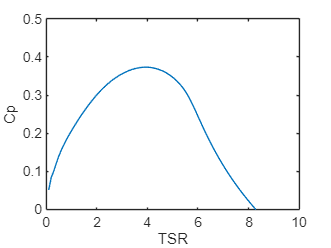

%Using slides (lubbock) method] (Only uses sg43 airfoil rn)
%Seems to scale wierdly with lambda
Wlist=zeros(91,slices); %added this (lothaire)
philist = zeros(91, slices); %added this (lothaire) just to store values
storePw = zeros(1,91);
storea = zeros(91,slices);
storealpha = zeros(91,slices);
for ratiolambda = 0.1:0.1:9.1
    alist = [];
    alphalist = [];
    ReList = [];
angvel = (ratiolambda*FreeNormVel)/(Diameter/2);
fn=0;
Pw = 0;
Torque = 0;
Wtot = 0;
TwistEquation = @(R,DesAlph) (atand(Diameter./(3.55*(R).^1.06*ratiolambda))-DesAlph); 
ChordEquation = @(R,LiftC) (((16*pi*R)/(N*LiftC)).*sin((1/3)*atan(Diameter./(2*R*ratiolambda))).^2);
for R = linspace(RootStart,(Diameter/2),slices)
i = find(R <= AirfoilChangeR, 1); if isempty(i), i = length(AirfoilChangeR)+1; end
added = (i-1)/100;
a = aopt;
adash = adashopt;
phi = (atand((1-a)*Diameter/(2*ratiolambda*R*(1+adash))));
phi1 = phi + 10; 
brnum = 0 ;
while abs(phi - phi1) > 0.001
    brnum = brnum+1;
Alpha = (-(TwistEquation(R,DesAlpha(i)) - phi));
W = sqrt(((angvel*R)^2)+(FreeNormVel*(1-a))^2);
Re(i) = ((W*(ChordEquation(R,LiftCoef(i))+added))/kVisc);
% DesAlpha(i) = interp1(Re_grid, DesAlpha_table(i,:), Re(i), 'linear', 'extrap');

% Extract the 2D slices from CL_table and CD_table
cl_slice = squeeze(CL_table(i,:,:));
cd_slice = squeeze(CD_table(i,:,:));

% Transpose if needed to match grid dimensions
if size(cl_slice,1) ~= length(alpha_grid)
    cl_slice = cl_slice.';
    cd_slice = cd_slice.';
end


% Create interpolants with extrapolation
% Replace current interpolants with safer ones
liftInterp = griddedInterpolant({alpha_grid, Re_grid}, cl_slice, 'linear', 'linear');
liftInterp.ExtrapolationMethod = 'linear';

dragInterp = griddedInterpolant({alpha_grid, Re_grid}, cd_slice, 'linear', 'linear');
dragInterp.ExtrapolationMethod = 'linear';


% Interpolate lift and drag coefficients
CL = liftInterp(Alpha, Re(i));
CD = dragInterp(Alpha, Re(i));

% Store coefficients
LiftCoef(length(AirfoilChangeR)+2) = CL;
DragCoef(length(AirfoilChangeR)+2) = CD;


% to use the stall correction function, we would probably also need an
% array of Cd0 and AOA0 for the arifoils, these are the final two inputs in the equation
% [LiftCoef(length(AirfoilChangeR)+2),DragCoef(length(AirfoilChangeR)+2)] =
% stall_corrected(XFOIL(idx2,(2+3*(i-1))),XFOIL(idx2,(3+3*(i-1))),Alpha,(R/(Diameter/2)),ChordEquation(R,LiftCoef(i)),angvel,0.04125,-1); 
a_new = ratiolambda*(LiftCoef(length(AirfoilChangeR)+2)*N*(ChordEquation(R,LiftCoef(i))+added))/(Diameter*pi*4*sind(phi));
a = 0.7*a + 0.3*a_new;  % Smooth update

adash_new = 1/(((2*pi*4*sind(phi)*cosd(phi))/(LiftCoef(length(AirfoilChangeR)+2)*N*(ChordEquation(R,LiftCoef(i))+added))) - 1);
adash = 0.7*adash + 0.3*adash_new;  % Smooth update
a = min(max(a, 0), 0.95);        % Clamp a to [0, 0.95]
adash = min(max(adash, 0), 0.95);  % Clamp adash similarly
phi1 = phi;
phi_new = atand((1-a)*Diameter/(2*ratiolambda*R*(1+adash)));
phi = 0.5*phi + 0.5*phi_new;
if brnum == 10
    break
end
end
alphalist = [alphalist,Alpha];
alist = [alist,a];
W = sqrt(((angvel*R)^2)+(FreeNormVel*(1-a))^2);
ReList = [ReList,((W*(ChordEquation(R,LiftCoef(i))+added))/kVisc)];
% Wlist(round((ratiolambda-1)/0.1)+1, round((R - RootStart)/((Diameter/2 - RootStart)/(slices-1))) + 1) = W; %added this (lothaire) just to store values
% philist(round((ratiolambda-1)/0.1)+1, round((R - RootStart)/((Diameter/2 - RootStart)/(slices-1))) + 1) = phi; %added this (lothaire) just to store values
Wtot = Wtot+W;
Ftip = (2/pi)*acos(exp(-(N/2)*(((Diameter/2)-R)/(R*sind(phi))))); %Prandtls tip loss
Froot = (2/pi)*acos(exp(-(N/2)*((R-(RootStart))/(R*sind(phi))))); %Prandtls root loss
Ftotal = Ftip*Froot; %total tip and root corrections
dR = ((Diameter/2)-(RootStart))/slices;
ForceTot = N * 0.5 * row * W^2 * (ChordEquation(R,LiftCoef(i))+added) * (LiftCoef(length(AirfoilChangeR)+2)*sind(phi)-DragCoef(length(AirfoilChangeR)+2)*cosd(phi));
dPw = (ForceTot * R - 0.03) * angvel * dR; %0.03 accounts for motor resistance
Pw = Pw + dPw*Ftotal;
Torque = Torque + (ForceTot * R - 0.03) * dR*Ftotal;

end
storePw(int32(ratiolambda*10)) = Pw;
storeTorque(int32(ratiolambda*10)) = Torque;
storea(int32(ratiolambda*10),:) = alist;
storealpha(int32(ratiolambda*10),:) = alphalist;
storeRe(int32(ratiolambda*10),:) = ReList;
StoreW(int32(ratiolambda*10)) = Wtot/slices;
end
[val, optlambda] = max(storePw);
plot(0.1:0.1:9.1,storePw/Constant)
xlabel('TSR')
ylabel('Cp')
ylim([0,0.5])

Power = val

Power = 44.0932

storeRe(optlambda,:)

ans = 1.0e+05 *

    0.5647    0.5804    0.5952    0.6092    0.6225    0.6351    0.6471    0.6585    0.6694    0.6798    0.6898    0.6992    0.7083    0.7170    0.7253    0.7333    0.7409    0.7482    0.7552    0.7619    0.8519    0.8602    0.8682    0.8759    0.8835    0.8908    0.8979    0.9048    0.9115    0.9180    0.9244    0.9306    0.9366    0.9425    0.9483    0.9539    0.9594    0.9648    0.9701    0.9752    0.9803    0.9852    0.9901    0.9948    0.9995    1.0040    1.0085    1.0129    1.0173    1.0215


mean(storeRe(optlambda,1:37))

ans = 7.8377e+04

mean(storeRe(optlambda,38:end))

ans = 1.0862e+05

storealpha(optlambda,:)

ans =    10.9146   10.8555   10.7770   10.6827   10.5759   10.4593   10.3372   10.2106   10.0810    9.9495    9.8175    9.6865    9.5575    9.4320    9.3100    9.1916    9.0779    8.9691    8.8655    8.7675    7.4426    7.3504    7.2613    7.1753    7.0914    7.0122    6.9349    6.8605    6.7886    6.7194    6.6526    6.5918    6.5342    6.4788    6.4255    6.3743    6.3250    6.2780    6.2334    6.1910    6.1502    6.1113    6.0737    6.0374    6.0023    5.9685    5.9360    5.9044    5.8739    5.8442


% storea(optlambda,:) %Array of a at optimum TSR
% StoreW(optlambda) %AvgVelociity
% plot(linspace(RootStart,Diameter/2,slices),storealpha(optlambda,:)) % %plots alpha along blade
optlambda = (optlambda)/10

optlambda = 3.9000

StartingTorque = storeTorque(2)

StartingTorque = 1.2381

%Could maybe optimise the following to allow varying of splits and airfoils etc
r(2,:) = AirfoilChangeR:0.001:(Diameter/2);
r(1,:) = NaN;
Rt2Chnge = (RootStart):0.001:AirfoilChangeR;
r(1,1:length(Rt2Chnge)) = Rt2Chnge;

% % NEW METHOD
figure
ChordEquation = @(R,LiftC) (((16*pi*R)/(N*LiftC)).*sin((1/3)*atan(Diameter./(2*R*optlambda))).^2);
%MAKE EQUATION TIP END OFFSET BY 1/1.5CM BUT ROOT BE NON OFFSET
for i = 1:2
    added = (i-1)/100;
    plot(r(i,:),(ChordEquation(r(i,:),LiftCoef(i))+added))
    hold on
end

Chord(1,:) = [r(1,1:length(Rt2Chnge)),r(2,:)];
Chord(2,:)= [ChordEquation(r(1,1:length(Rt2Chnge)),LiftCoef(1)),ChordEquation(r(2,:), LiftCoef(2))+0.01]

Chord =     0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500    0.0510    0.0520    0.0530    0.0540    0.0550    0.0560    0.0570    0.0580    0.0590    0.0600    0.0610    0.0620    0.0630    0.0640    0.0650    0.0660    0.0670    0.0680    0.0690    0.0700    0.0710    0.0720    0.0730    0.0740    0.0750    0.0760    0.0769    0.0779    0.0789    0.0799    0.0809    0.0819    0.0829    0.0839
    0.0867    0.0872    0.0878    0.0882    0.0886    0.0890    0.0893    0.0895    0.0897    0.0899    0.0900    0.0901    0.0902    0.0902    0.0902    0.0901    0.0900    0.0899    0.0898    0.0897    0.0895    0.0893    0.0891    0.0888    0.0886    0.0883    0.0880    0.0877    0.0874    0.0871    0.0867    0.0864    0.0860    0.0857    0.0853    0.0849    0.0845    0.0841    0.0837    0.0833    0.0829    0.0825    0.0921    0.0917    0.0913    0.0909    0.0905    0.0900    0.0896 

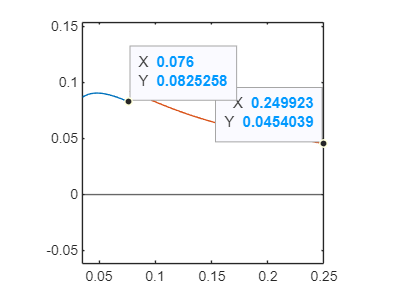

% MeanChord = mean([ChordEquation(r(2,:)),ChordEquation(r(1,1:length(Rt2Chnge)))])
yline(0)
set(gca,'DataAspectRatio',[1 1 1],'PlotBoxAspectRatio',[1 1 1],'XLim',[RootStart,(Diameter/2)])
hold off



% To find twist
figure
TwistEquation = @(R,DesAlph) (atand(Diameter./(3.55*(R.^1.06)*optlambda))-DesAlph);  
for i = 1:2
plot(r(i,:),TwistEquation(r(i,:),ForTwstGrphAlpha(i)))
hold on
end
Twist(1,:) = [r(1,1:length(Rt2Chnge)),r(2,:)];
Twist(2,:) = [TwistEquation(r(1,1:length(Rt2Chnge)),ForTwstGrphAlpha(1)),TwistEquation(r(2,:),ForTwstGrphAlpha(2))]

Twist =     0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500    0.0510    0.0520    0.0530    0.0540    0.0550    0.0560    0.0570    0.0580    0.0590    0.0600    0.0610    0.0620    0.0630    0.0640    0.0650    0.0660    0.0670    0.0680    0.0690    0.0700    0.0710    0.0720    0.0730    0.0740    0.0750    0.0760    0.0769    0.0779    0.0789    0.0799    0.0809    0.0819    0.0829    0.0839
   44.6009   43.7653   42.9478   42.1482   41.3662   40.6016   39.8540   39.1233   38.4090   37.7109   37.0287   36.3619   35.7104   35.0737   34.4516   33.8437   33.2496   32.6690   32.1017   31.5472   31.0053   30.4756   29.9579   29.4517   28.9569   28.4731   28.0000   27.5374   27.0850   26.6424   26.2095   25.7860   25.3716   24.9661   24.5693   24.1808   23.8006   23.4283   23.0638   22.7068   22.3572   22.0147   21.7048   21.3755   21.0529   20.7367   20.4268   20.1230   19.8251 

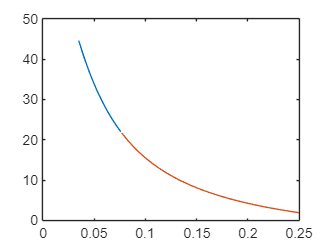

yline(0)
hold off

% % LUBBOCK METHOD
% % To find chord distribution
% AreaBlade = (((Diameter/2)^2)/(N*ratiolambda))
% ChordIntegral = @(k) (integral(@(x) (k./x),(Diameter/20),(Diameter/2))-AreaBlade)
% k = fzero(ChordIntegral,0.1)
% ChordEquation = @(R) (k./R)
% plot(r,ChordEquation(r))
% yline(0)
% set(gca,'DataAspectRatio',[1 1 1],'PlotBoxAspectRatio',[1 1 1],'XLim',[Diameter/20,(Diameter/2)])
% hold off

% % To find twist
% figure
% for i = 1:2
% TwistEquation = @(R) (atand(Diameter./(3*R*ratiolambda))-DesAlpha(i));
% plot(r(i,:),TwistEquation(r(i,:)))
% hold on
% end
% yline(0)
% hold off

% FOR WHATEVER REASON THIS CODE USING I2A IS WRONG (IDK WHY)
% boundr(1:2) = [(Diameter/2),(Diameter/20)];
% for i = 1:2
% ChordEquation = @(R) (((16*pi*R)/(N*LiftCoef(i))).*sin((1/3)*atan(Diameter./(2*R*ratiolambda))).^2); %try to remove later for ease of code
% Fn(i) = 0; %Found iteratively, Loop till convergence
%  Fn1(i) = 10;
% while abs(Fn(i) - Fn1(i)) > 0.00001
%  angvel = (ratiolambda*FreeNormVel)/(Diameter/2);
%  NormVel = (FreeNormVel/2) - (1/2)*sqrt((FreeNormVel^2) + (8*Fn(i))/(row*pi*Diameter^2)); %the second part applies the induced stuff
%  TangVel = @(x) (angvel*x); %func of R
%  TotalVel =  @(x) (sqrt((x.^2)+NormVel^2)); %func of TangVel
%  dAOA =  @(x) (atand(NormVel./x)); %func of TangVel
% 
%  SingleIntegral = @(a,b,c) (1/2*row*(a.^2).*c.*(LiftCoef(i)*cosd(b)+(sind(b)*DragCoef(i))));
%  Fn1(i) = Fn(i);
%  Fn(i) = (N)*integral(@(x) SingleIntegral(TotalVel(TangVel(x)),dAOA(TangVel(x)),ChordEquation(x)),(Diameter/8),boundr(i));
% end
% SingleIntegralp = @(a,b,c) (1/2*row*(a.^2).*c.*(DragCoef(i)*cosd(b)-(sind(b)*LiftCoef(i))));
% Pw(i) = (N)*angvel*integral(@(x) SingleIntegralp(TotalVel(TangVel(x)),dAOA(TangVel(x)),ChordEquation(x).*x),(Diameter/8),boundr(i));
% end
% Fn =  Fn(1) - Fn(2)
% Pw = Pw(1) - Pw(2)

function [Cl,Cd] = stall_corrected(xfoil_cl,xfoil_cd,Alpha,r_ratio,c,angvel,Cd0,AoA0) %function to apply stall correction
    if r_ratio>0.3 && r_ratio<0.95 %from a paper, how the shift value varies along the blade
        % these equations are from the 1998 AIAA paper
        clp = 2*pi*(Alpha-AoA0);
        cr_ratio = c/(r_ratio*(0.245)); %this has the radius in it, in case that changes in the future
        big_lamb = ((angvel)*0.245)/sqrt(100 + ((angvel)*0.245)^2);
        fl = ( (1.6*cr_ratio/0.1267) * ( (1-cr_ratio^(1/(big_lamb*r_ratio)) ) / (1+cr_ratio^(1/(big_lamb*r_ratio))) )-1) / (2*pi); 
        fd = ( (1.6*cr_ratio/0.1267) * ( (1-cr_ratio^(1/(2*big_lamb*r_ratio)) ) / (1+cr_ratio^(1/(2*big_lamb*r_ratio))) )-1) / (2*pi); 
        del_cl =fl*(clp-xfoil_cl);
        del_cd =fd*(xfoil_cd-Cd0);
        Cl = xfoil_cl+del_cl;
        Cd = xfoil_cd-del_cd;
    else
        Cl = xfoil_cl;
        Cd = xfoil_cd;
    end
end